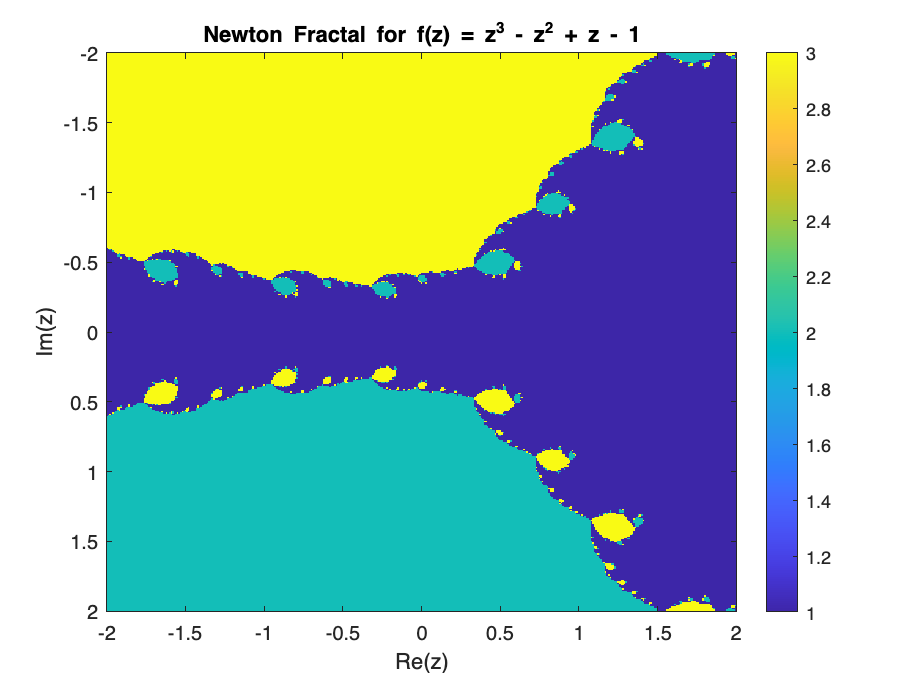

% Define the function f(z) and its derivative
f = @(z) z.^3 - z.^2 + z - 1;
df = @(z) 3*z.^2 - 2*z + 1;

% Create a grid of complex numbers
x = linspace(-2, 2, 401);
y = linspace(-2, 2, 401);
[X, Y] = meshgrid(x, y);
Z = X + 1j * Y;

% Initialize array to store the reached roots
reached_roots = zeros(size(Z));

% Roots of the function f(z)
function_roots = roots([1, -1, 1, -1]);

% Iterate over each point in the grid
for i = 1:numel(Z)
    [root, ~] = newton_method(Z(i), f, df, 1e-6, 20);
    % Find the index of the root reached
    [~, idx] = min(abs(function_roots - root));
    reached_roots(i) = idx;
end

% Plot the fractal
imagesc(x, y, reached_roots);
colorbar;
title('Newton Fractal for f(z) = z^3 - z^2 + z - 1');
xlabel('Re(z)');
ylabel('Im(z)');

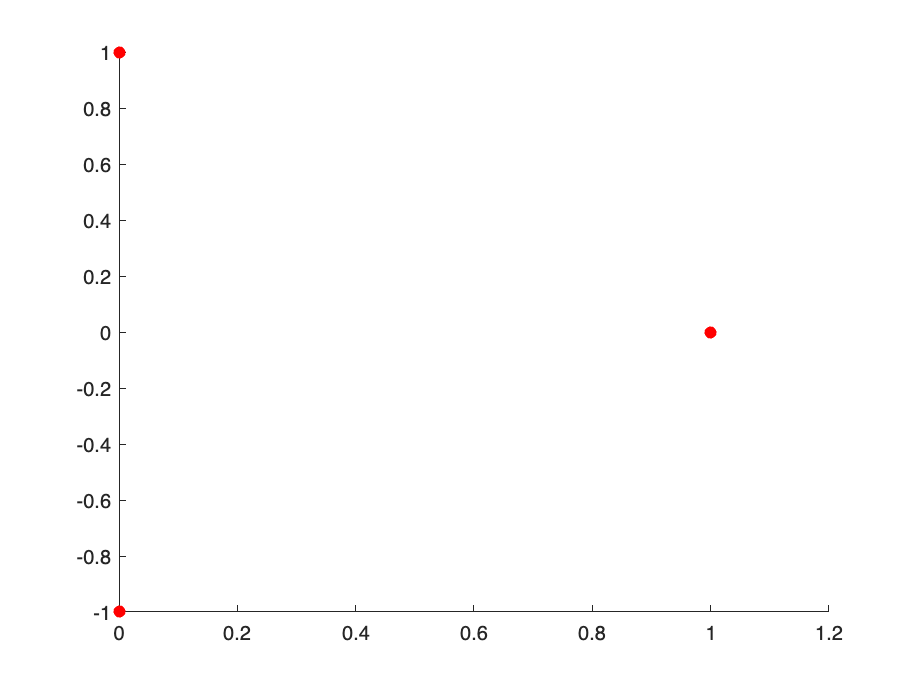


% Plot the roots of the function f(z)
scatter(real(function_roots), imag(function_roots), 'red', 'filled');